# PD

## Plant

Gs = tf(0.129,[0.00113 0.0844 0])

Gs =
 
          0.129
  ----------------------
  0.00113 s^2 + 0.0844 s
 
Continuous-time transfer function.



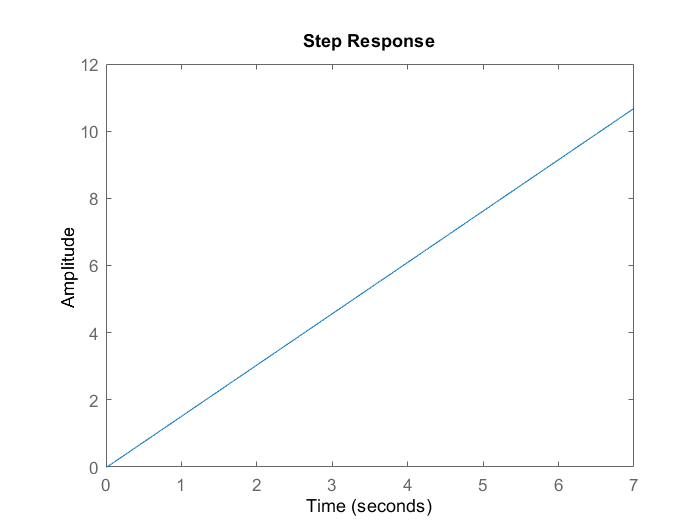

step(Gs)

# Controller

k = 1

k = 1

Cs = tf([1 80], 1)

Cs =
 
  s + 80
 
Continuous-time transfer function.



sysCsGs = series(k*Cs, Gs)

sysCsGs =
 
     0.129 s + 10.32
  ----------------------
  0.00113 s^2 + 0.0844 s
 
Continuous-time transfer function.



# Evaluation of k

% The num of C*G
num = [0.129 , 10.32];
% The den of C*G
den = [0.00213 , 0.0844 , 0];
% num of C*G for s = s_d
numval = polyval(num,-40+40*1j);
% den of C*G for s = s_d
denval = polyval(den,-40+40*1j);
value = denval/numval;



$$K=\frac{1}{{\left|C\left(s\right)*G\left(s\right)\right|}_{s_d } }$$


k = abs(value)

k = 0.6605

T = Cs * Gs

T =
 
     0.129 s + 10.32
  ----------------------
  0.00113 s^2 + 0.0844 s
 
Continuous-time transfer function.



T_c = feedback(T, 1);
stepinfo(T_c)

ans = struct with fields:
        RiseTime: 0.0180
    SettlingTime: 0.0298
     SettlingMin: 0.9020
     SettlingMax: 1.0016
       Overshoot: 0.1566
      Undershoot: 0
            Peak: 1.0016
        PeakTime: 0.0541


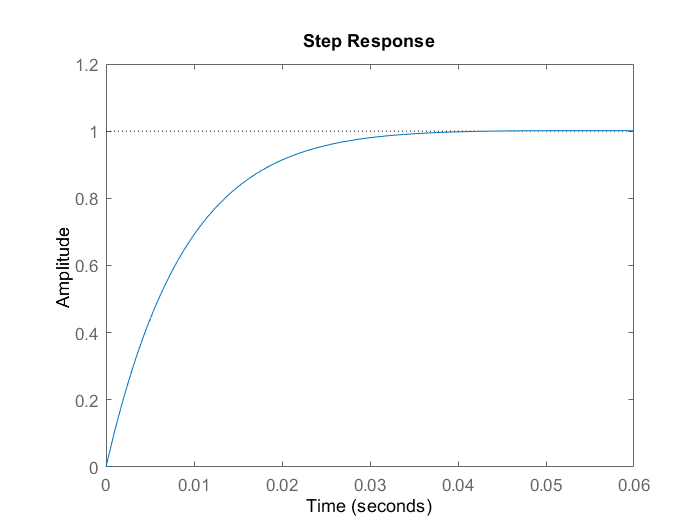

step(T_c)

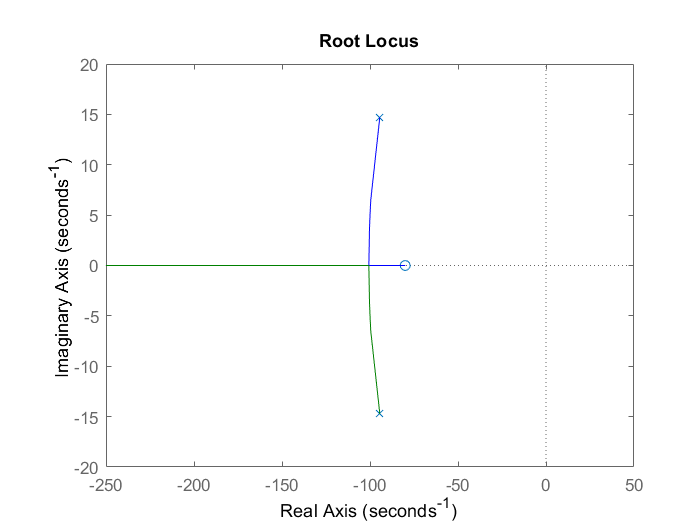

rlocus(T_c)